# Lines

## Creating a line

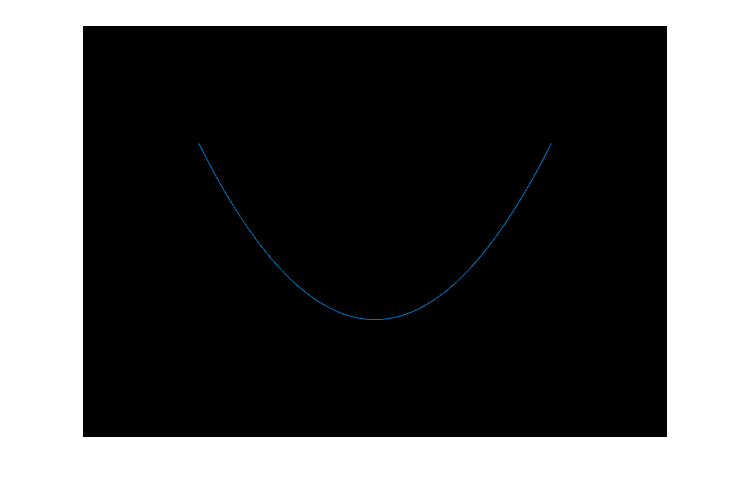

f = fvclear;

x = (-1:0.01:1)';
y1 = x.^2;
XY1 = [x y1];

fvLine(XY1);
f.Snapshot;

## Creating multiple lines

Nan coordinates disconnects the lines

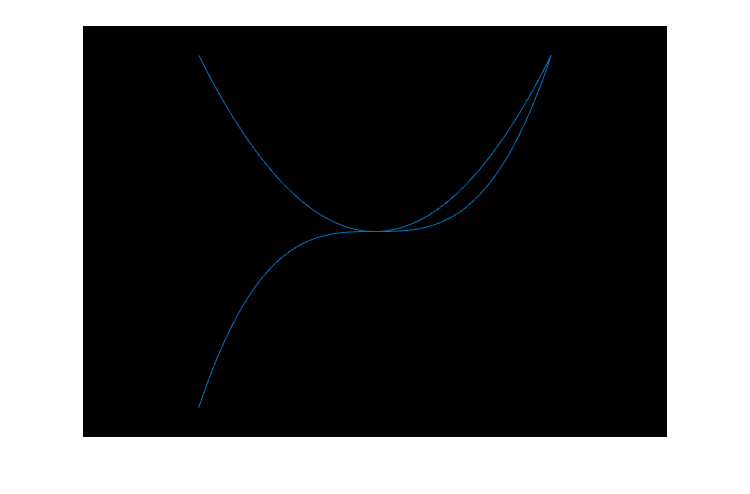

y2 = x.^3;
XY2 = [x y2];

XY3 = [XY1 ; nan nan ; XY2];

fvLine(XY3);
f.Snapshot;

## Assign different colors to the lines

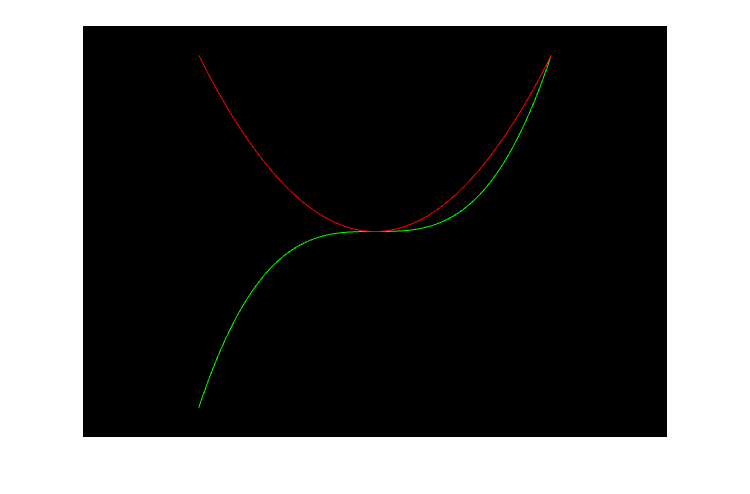

colorList = [1 0 0 ; 0 1 0];

idx0 = zeros(size(x));
colorIndex = uint8([idx0 ; idx0+1]);

fvLine(XY3,'Color',colorIndex,'Colormap',colorList);
f.Snapshot;

## Color 1 about X axis and the other about Y axis

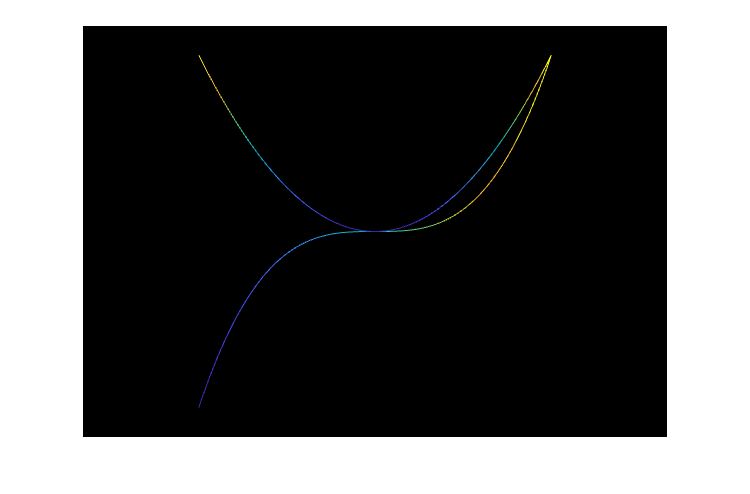

col = [rescale(y1) ; rescale(x)];

fvLine(XY3,'Color',col);
f.Snapshot;

## Change width

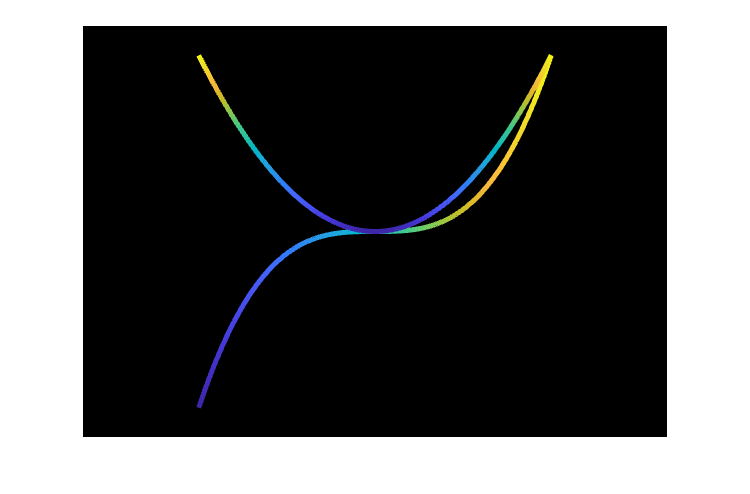

fvLine(XY3,'Color',col,'LineWidth',5);
f.Snapshot;

## Creating multiple single lines

Useful for things like graphs

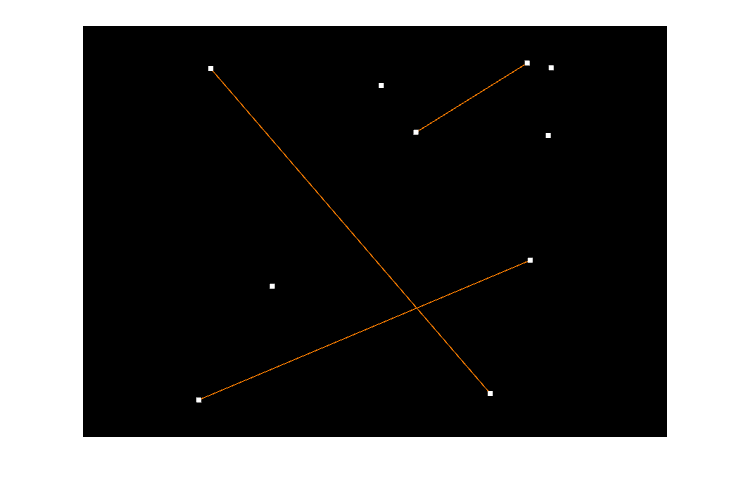

rng(0);
XY = rand(10,2);
connections = [1 2 ; 3 4 ; 5 6];
% connect the first XY to the second, etc

pc = fvPointcloud(XY,[1 1 1],'PointSize',5); % show nodes
fvLine(pc,XY,[1 0.5 0],'Index',connections(:),'LineStrip',false); % show connections
f.Snapshot;

## Everything also works in 3D

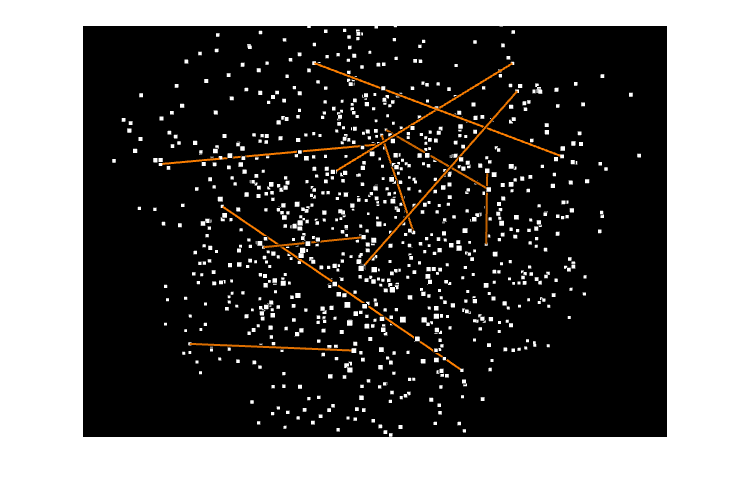

rng(0);
XYZ = rand(1000,3);
connections = randi(1000,10,2); % 10 random connections

pc = fvPointcloud(XYZ,[1 1 1],'PointSize',3,'PointUnit','world','PointSize',0.01); % show nodes
fvLine(pc,XYZ,[1 0.5 0],'Index',connections(:),'LineStrip',false,'LineWidth',2); % show connections
f.Snapshot;